# **변경사항**

**2023.01.26**

- 3d plot 시점 정해서 svg로 추출

- 한 개의 channel로만 구성된 community의 색깔 통일

- parameter 이름 변경 및 설명 보강

- node에 커서 올리면 community와 degree 정보 출력

- 좌표축 표시/숨기기 옵션

### 2023.01.10

- macOS 설정 방법 설명 추가

- node 삭제 기능 추가

- edge color 설정 방법 변경

- edge가 검은색으로 나오는 오류 해결

- svg export 추가

- 2d network 예시 추가

### 2022.08.25

- spike 개수가 2 이상인 경우에만 sync score 계산하도록 수정

- network plot에서 node 크기를 키우고 채널 번호가 보이도록 수정

# **Python 설치 및 설정 방법**

**MacOS on Apple Silicon (e.g., M1, M2)**

(1) [https://www.anaconda.com/products/distribution#macos](https://www.anaconda.com/products/distribution#macos) 에서 Anaconda Distribution 다운로드하여 설치

(2) terminal 실행

(3) 아래 명령어 입력하여 가상환경 생성

- `matlab_python`은 가상환경 이름이며 다른 이름으로 바꾸어도 됨

- `python==3.9.2` 는` 3.9.2 `버전의 파이썬을 설치한다는 뜻이며 다른 버전으로 바꾸어도 됨

`(4) 아래 명령어 입력하여 가상환경 활성화. (matlab_python)이라는 문구가 뜬다면 성공`

`(5) 가상환경이 활성화 된 상태에서 아래 명령어를 한 줄씩 입력하여 필요한 패키지 설치`

`(6) python 설치 경로 찾기`

    [1] 가상환경이 활성화 된 상태에서 terminal에 아래 명령어를 입력하여 python을 실행  

   [2]  python이 실행된 상태에서 terminal에 아래 명령어를 입력하여 설치된 파이썬의 경로를 출력

    이 내용을 복사합니다

**Windows 10**

- [https://www.python.org/downloads/windows/](https://www.python.org/downloads/windows/) 에서 python 3.7, 3.8, 3.9 버전 중 하나를 windows installer로 다운로드받습니다.

- [https://wikidocs.net/8](https://wikidocs.net/8) 링크의 설명을 따라하여 설치를 완료합니다. Add Python 3.x to PATH 옵션을 꼭 체크합니다.

- windows powershell을 실행합니다. 윈도우 10이면 기본적으로 설치되어 있습니다.

-  powershell 창에 바로 아래 내용을 한 줄씩 입력하고 엔터를 칩니다.  각 명령어는 패키지 하나를 설치하는 명령어입니다. 실행되지 않으면 pip3 대신 pip를 입력합니다.

`pyspike 설치 시 io.h 파일이 없다는 오류 메시지가 나오면 `[`https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/`](https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/)` 에서 windows 10 sdk를 설치합니다.`

         5. 입력창에 `python`을 입력하여 python을 실행합니다. python 버전이 설치한 버전과 일치하는지 확인합니다.

          6. 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다(저는 macos에서 진행했기 때문에 윈도우와 파이썬 경로가 다릅니다).

# **1. 2d network 그리기**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

- **network plot 그리기(3d)**

## **1.1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/jmmoon/Documents/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 소요시간 측정

Elapsed time is 40.672626 seconds.


## **1.2. networkAnalyzer 인스턴스 생성**

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/jmmoon/Documents/GitHub/neurosignal-matlab", "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python"); %  networkAnalyzer 클래스 인스턴스 생성

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python"
          Library: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/lib/libpython3.9.dylib"
             Home: "/Users/jmmoon/opt/anaconda3/envs/matlab_python"
           Status: Terminated
    ExecutionMode: OutOfProcess


## **1.3. 데이터 파일을 networkAnalyzer에 전달 **

na.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

Deleted previous data
Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
num

## **1.4. 사용하지 않는 채널 제거**

여기서는 17번-64번 채널을 모두 제거하겠습니다.

                %채널 번호
na.deleteChannel(17);

Deleted channal 17


idx_channelList = 17

63 channels left


na.deleteChannel(18);

Deleted channal 18


idx_channelList = 17

62 channels left


na.deleteChannel(19);

Deleted channal 19


idx_channelList = 17

61 channels left


na.deleteChannel(20);

Deleted channal 20


idx_channelList = 17

60 channels left


na.deleteChannel(21);

Deleted channal 21


idx_channelList = 17

59 channels left


na.deleteChannel(22);

Deleted channal 22


idx_channelList = 17

58 channels left


na.deleteChannel(23);

Deleted channal 23


idx_channelList = 17

57 channels left


na.deleteChannel(24);

Deleted channal 24


idx_channelList = 17

56 channels left


na.deleteChannel(25);

Deleted channal 25


idx_channelList = 17

55 channels left


na.deleteChannel(26);

Deleted channal 26


idx_channelList = 17

54 channels left


na.deleteChannel(27);

Deleted channal 27


idx_channelList = 17

53 channels left


na.deleteChannel(28);

Deleted channal 28


idx_channelList = 17

52 channels left


na.deleteChannel(29);

Deleted channal 29


idx_channelList = 17

51 channels left


na.deleteChannel(30);

Deleted channal 30


idx_channelList = 17

50 channels left


na.deleteChannel(31);

Deleted channal 31


idx_channelList = 17

49 channels left


na.deleteChannel(32);

Deleted channal 32


idx_channelList = 17

48 channels left


na.deleteChannel(33);

Deleted channal 33


idx_channelList = 17

47 channels left


na.deleteChannel(34);

Deleted channal 34


idx_channelList = 17

46 channels left


na.deleteChannel(35);

Deleted channal 35


idx_channelList = 17

45 channels left


na.deleteChannel(36);

Deleted channal 36


idx_channelList = 17

44 channels left


na.deleteChannel(37);

Deleted channal 37


idx_channelList = 17

43 channels left


na.deleteChannel(38);

Deleted channal 38


idx_channelList = 17

42 channels left


na.deleteChannel(39);

Deleted channal 39


idx_channelList = 17

41 channels left


na.deleteChannel(40);

Deleted channal 40


idx_channelList = 17

40 channels left


na.deleteChannel(41);

Deleted channal 41


idx_channelList = 17

39 channels left


na.deleteChannel(42);

Deleted channal 42


idx_channelList = 17

38 channels left


na.deleteChannel(43);

Deleted channal 43


idx_channelList = 17

37 channels left


na.deleteChannel(44);

Deleted channal 44


idx_channelList = 17

36 channels left


na.deleteChannel(45);

Deleted channal 45


idx_channelList = 17

35 channels left


na.deleteChannel(46);

Deleted channal 46


idx_channelList = 17

34 channels left


na.deleteChannel(47);

Deleted channal 47


idx_channelList = 17

33 channels left


na.deleteChannel(48);

Deleted channal 48


idx_channelList = 17

32 channels left


na.deleteChannel(49);

Deleted channal 49


idx_channelList = 17

31 channels left


na.deleteChannel(50);

Deleted channal 50


idx_channelList = 17

30 channels left


na.deleteChannel(51);

Deleted channal 51


idx_channelList = 17

29 channels left


na.deleteChannel(52);

Deleted channal 52


idx_channelList = 17

28 channels left


na.deleteChannel(53);

Deleted channal 53


idx_channelList = 17

27 channels left


na.deleteChannel(54);

Deleted channal 54


idx_channelList = 17

26 channels left


na.deleteChannel(55);

Deleted channal 55


idx_channelList = 17

25 channels left


na.deleteChannel(56);

Deleted channal 56


idx_channelList = 17

24 channels left


na.deleteChannel(57);

Deleted channal 57


idx_channelList = 17

23 channels left


na.deleteChannel(58);

Deleted channal 58


idx_channelList = 17

22 channels left


na.deleteChannel(59);

Deleted channal 59


idx_channelList = 17

21 channels left


na.deleteChannel(60);

Deleted channal 60


idx_channelList = 17

20 channels left


na.deleteChannel(61);

Deleted channal 61


idx_channelList = 17

19 channels left


na.deleteChannel(62);

Deleted channal 62


idx_channelList = 17

18 channels left


na.deleteChannel(63);

Deleted channal 63


idx_channelList = 17

17 channels left


na.deleteChannel(64);

Deleted channal 64


idx_channelList = 17

16 channels left


## **1.5. 노드 좌표 설정**

2d network이므로 높이를 모두 0으로 설정합니다.

%                 channlNum x  y  z
na.setChannelPosition3d(1 , 0, 0, 0)

set channel 1's position as (0.000000, 0.000000, 0.000000)


na.setChannelPosition3d(2 , 0, 1, 0)

set channel 2's position as (0.000000, 1.000000, 0.000000)


na.setChannelPosition3d(3 , 0, 2, 0)

set channel 3's position as (0.000000, 2.000000, 0.000000)


na.setChannelPosition3d(4 , 0, 3, 0)

set channel 4's position as (0.000000, 3.000000, 0.000000)


na.setChannelPosition3d(5 , 1, 0, 0)

set channel 5's position as (1.000000, 0.000000, 0.000000)


na.setChannelPosition3d(6 , 1, 1, 0)

set channel 6's position as (1.000000, 1.000000, 0.000000)


na.setChannelPosition3d(7 , 1, 2, 0)

set channel 7's position as (1.000000, 2.000000, 0.000000)


na.setChannelPosition3d(8 , 1, 3, 0)

set channel 8's position as (1.000000, 3.000000, 0.000000)



na.setChannelPosition3d(9 , 2, 0, 0)

set channel 9's position as (2.000000, 0.000000, 0.000000)


na.setChannelPosition3d(10, 2, 1, 0)

set channel 10's position as (2.000000, 1.000000, 0.000000)


na.setChannelPosition3d(11, 2, 2, 0)

set channel 11's position as (2.000000, 2.000000, 0.000000)


na.setChannelPosition3d(12, 2, 3, 0)

set channel 12's position as (2.000000, 3.000000, 0.000000)


na.setChannelPosition3d(13, 3, 0, 0)

set channel 13's position as (3.000000, 0.000000, 0.000000)


na.setChannelPosition3d(14, 3, 1, 0)

set channel 14's position as (3.000000, 1.000000, 0.000000)


na.setChannelPosition3d(15, 3, 2, 0)

set channel 15's position as (3.000000, 2.000000, 0.000000)


na.setChannelPosition3d(16, 3, 3, 0)

set channel 16's position as (3.000000, 3.000000, 0.000000)


## **1.6. spike detection**

na.bandPass([300,3000])
na.detectSpikes(4,2,2);

channel 1 number of spikes found : 61
channel 2 number of spikes found : 131
channel 3 number of spikes found : 140
channel 4 number of spikes found : 313
channel 5 number of spikes found : 351
channel 6 number of spikes found : 86
channel 7 number of spikes found : 82
channel 8 number of spikes found : 175
channel 9 number of spikes found : 147
channel 10 number of spikes found : 108
channel 11 number of spikes found : 29
channel 12 number of spikes found : 322
channel 13 number of spikes found : 348
channel 14 number of spikes found : 336
channel 15 number of spikes found : 353
channel 16 number of spikes found : 15


## **1.7. sync score 계산 및 확인**

- pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도 (= 1 - 거리)를 측정합니다.

- spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 sync score 계산값이 NaN이 됩니다.

- NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

- thres 값을 0,5로 설정하면, sync score 0.5 이상일 경우에만 연결된 것으로 간주합니다.

thres = 0.5; %sync score 0.5 이상일 경우에만 연결된 것으로 간주 (network를 그릴 때에만 적용됨)
na.spikeDist(thres);

na =   networkAnalyzer with properties:

          spikeTrains: []
             channels: [16×1 containers.Map]
          channelList: [16×1 double]
            nChannels: 16
              distMat: []
             filepath: "/Users/jmmoon/Documents/GitHub/neurosignal-matlab"
           pythonpath: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python"
          ChannelList: []
            positions: [16×5 double]
           syncScores: []
            nConnects: []
                thres: 0.5000
    is_spike_detected: 1


train_1 =         1151        2775        3591        7433       10103       10689       12313       13129       14753       15391       15977       17430       18647       19224       20448       20856       21086       24350       24520       25337       25567       26391       35485       36015       36135       36559       36711       37143       38069       38238       38998       39094       39154       40389       40585       40634       41406       41765       41838       41908       41994       42079       42140       42206       42277       42349       42405       42497       42565       42614


train_2 =          335         513         735         913        1142        1551        2366        2775        3769        4577        4807        5215        5393        5622        5712        5801        6209        6431        6617        7025        7247        7654        8248        8471        8879        9056        9368        9465       10095       10510       10681       11319       11726       11889       12135       12543       12943       13128       14167       14574       14737       15553       15799       16199       16607       17193       18009       18238       18417       19454


nSpikes_1 = 61

nSpikes_2 = 131

dist_now = 0.5208

loop 1

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 2

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 3

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 4

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 5

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 6

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 7

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 8

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 9

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 10

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 11

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 12

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 13

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 14

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 15

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 16

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 17

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 18

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 19

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 20

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 21

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 22

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 23

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 24

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 25

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 26

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 27

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 28

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 29

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 30

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 31

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 32

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 33

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 34

normalizer_now = 0.1042

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 35

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 36

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 37

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 38

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 39

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 40

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 41

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 42

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 43

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 44

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 45

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 46

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 47

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 48

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 49

normalizer_now = 0.3021

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 50

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 51

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 52

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 53

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 54

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 55

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 56

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 57

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 58

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 59

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 60

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 61

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 62

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 63

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 64

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 65

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 66

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 67

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 68

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 69

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 70

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 71

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 72

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 73

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 74

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN 

loop 75

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917       NaN       NaN       NaN       NaN       NaN       NaN 

loop 76

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917       NaN       NaN       NaN       NaN       NaN       NaN 

loop 77

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917       NaN       NaN       NaN       NaN       NaN       NaN 

loop 78

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917       NaN       NaN       NaN       NaN       NaN       NaN 

loop 79

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917       NaN       NaN       NaN       NaN       NaN       NaN 

loop 80

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917       NaN       NaN       NaN       NaN       NaN       NaN 

loop 81

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708       NaN       NaN       NaN       NaN       NaN 

loop 82

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708       NaN       NaN       NaN       NaN 

loop 83

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 84

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 85

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 86

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 87

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 88

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 89

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 90

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 91

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 92

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 93

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 94

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 95

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 96

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 97

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 98

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 99

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 100

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 101

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 102

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 103

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 104

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 105

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 106

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 107

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 108

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 109

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 110

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 111

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 112

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 113

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 114

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 115

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 116

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 117

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 118

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 119

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 120

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 121

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 122

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 123

normalizer_now = 0.3021

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 124

normalizer_now = 0.3021

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 125

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 126

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 127

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 128

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 129

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 130

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 131

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 132

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 133

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 134

normalizer_now = 0.1354

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 135

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 136

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 137

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 138

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 139

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 140

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 141

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 142

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 143

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 144

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 145

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 146

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 147

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 148

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 149

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 150

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 151

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 152

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 153

normalizer_now = 0.3125

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 154

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 155

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 156

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 157

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 158

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 159

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 160

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 161

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 162

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 163

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 164

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 165

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 166

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 167

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 168

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 169

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 170

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 171

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 172

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 173

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 174

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 175

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 176

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 177

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 178

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 179

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 180

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 181

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 182

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 183

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 184

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 185

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 186

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 187

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 188

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 189

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 190

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 191

normalizer_now = 0.3542

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 192

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 193

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 194

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 195

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 196

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 197

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 198

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 199

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 200

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 201

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 202

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 203

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 204

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 205

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 206

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 207

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 208

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 209

normalizer_now = 0.1354

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 210

normalizer_now = 0.1250

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 211

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 212

normalizer_now = 0.1354

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 213

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 214

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 215

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 216

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 217

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 218

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 219

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 220

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 221

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 222

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 223

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 224

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 225

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 226

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 227

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 228

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 229

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 230

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 231

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 232

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 233

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 234

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 235

normalizer_now = 0.1250

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 236

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 237

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 238

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 239

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 240

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 241

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 242

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 243

normalizer_now = 0.3021

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 244

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 245

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 246

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 247

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 248

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 249

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 250

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 251

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 252

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 253

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 254

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 255

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 256

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 257

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 258

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 259

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 260

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 261

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 262

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 263

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 264

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 265

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 266

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 267

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 268

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 269

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 270

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 271

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 272

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 273

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 274

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 275

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 276

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 277

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 278

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 279

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 280

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 281

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 282

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 283

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 284

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 285

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 286

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 287

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 288

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 289

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 290

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 291

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 292

normalizer_now = 0.3021

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 293

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 294

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 295

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 296

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 297

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 298

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 299

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 300

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 301

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 302

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 303

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 304

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 305

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 306

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 307

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 308

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 309

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 310

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 311

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 312

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 313

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 314

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 315

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 316

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 317

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 318

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 319

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 320

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 321

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 322

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 323

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 324

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 325

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 326

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 327

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 328

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 329

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 330

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 331

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 332

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 333

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 334

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 335

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 336

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 337

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 338

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 339

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 340

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 341

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 342

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 343

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 344

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 345

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 346

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 347

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 348

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 349

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 350

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 351

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 352

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 353

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 354

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 355

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 356

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 357

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 358

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 359

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 360

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 361

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 362

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 363

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 364

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 365

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 366

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 367

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 368

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 369

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 370

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 371

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 372

normalizer_now = 0.3125

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 373

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 374

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 375

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 376

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 377

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 378

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 379

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 380

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 381

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 382

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 383

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 384

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 385

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 386

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 387

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 388

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 389

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 390

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 391

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 392

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 393

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 394

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 395

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 396

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 397

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 398

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 399

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 400

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 401

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 402

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 403

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 404

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 405

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 406

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 407

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 408

normalizer_now = 0.1354

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 409

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 410

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 411

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 412

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 413

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 414

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 415

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 416

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 417

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 418

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 419

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 420

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 421

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 422

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 423

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 424

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 425

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 426

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 427

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 428

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 429

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 430

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 431

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 432

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 433

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 434

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 435

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 436

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 437

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 438

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 439

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 440

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 441

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 442

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 443

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 444

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 445

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 446

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 447

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 448

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 449

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 450

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 451

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 452

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 453

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 454

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 455

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 456

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 457

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 458

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 459

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 460

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 461

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 462

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 463

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 464

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 465

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 466

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 467

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 468

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 469

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 470

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 471

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 472

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 473

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 474

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 475

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 476

normalizer_now = 0.3229

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 477

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 478

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 479

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 480

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 481

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 482

normalizer_now = 0.1354

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 483

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 484

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 485

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 486

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 487

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 488

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 489

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 490

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 491

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 492

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 493

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 494

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 495

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 496

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 497

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 498

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 499

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 500

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 501

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 502

normalizer_now = 0.3125

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 503

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 504

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 505

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 506

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 507

normalizer_now = 0.3125

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 508

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 509

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 510

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 511

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 512

normalizer_now = 0.1354

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 513

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 514

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 515

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 516

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 517

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 518

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 519

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 520

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 521

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 522

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 523

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 524

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 525

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 526

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 527

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 528

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 529

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 530

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 531

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 532

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 533

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 534

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 535

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 536

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 537

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 538

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 539

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 540

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 541

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 542

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 543

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 544

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 545

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 546

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 547

normalizer_now = 0.1250

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 548

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 549

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 550

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 551

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 552

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 553

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 554

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 555

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 556

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 557

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 558

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 559

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 560

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 561

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 562

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 563

normalizer_now = 0.2917

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 564

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 565

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 566

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 567

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 568

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 569

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 570

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 571

normalizer_now = 0.2188

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 572

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 573

normalizer_now = 0.2708

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 574

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 575

normalizer_now = 0.2813

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 576

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 577

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 578

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 579

normalizer_now = 0.1250

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 580

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 581

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 582

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 583

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 584

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 585

normalizer_now = 0.2604

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 586

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 587

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 588

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 589

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 590

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 591

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 592

normalizer_now = 0.1563

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 593

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 594

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 595

normalizer_now = 0.1667

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 596

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 597

normalizer_now = 0.2396

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 598

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 599

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 600

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 601

normalizer_now = 0.1458

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 602

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 603

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 604

normalizer_now = 0.2500

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 605

normalizer_now = 0.1979

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 606

normalizer_now = 0.1875

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 607

normalizer_now = 0.1771

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 608

normalizer_now = 0.2292

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 609

normalizer_now = 0.2083

normalizer_save_now =   Python ndarray:

  Columns 1 through 999

       NaN    0.3021    0.3438    0.3333    0.3542    0.3021    0.2812    0.2812    0.3125    0.3438    0.3438    0.3438    0.3333    0.2812    0.2708    0.3125    0.3438    0.2604    0.2708    0.2500    0.3021    0.3021    0.3021    0.3438    0.3333    0.3229    0.3021    0.3021    0.3229    0.3125    0.3125    0.2812    0.3125    0.2917    0.4167    0.3125    0.2708    0.3229    0.2396    0.2500    0.2708    0.3542    0.3333    0.3646    0.3229    0.2708    0.3125    0.2708    0.3438    0.2188    0.2708    0.3333    0.2708    0.3438    0.2604    0.3125    0.2812    0.3438    0.3438    0.2917    0.2708    0.3438    0.2500    0.3021    0.3229    0.3229    0.3125    0.3229    0.2812    0.2604    0.3333    0.2708    0.3333    0.3333    0.3229    0.3021    0.3750    0.3125    0.3542    0.2917    0.2708    0.2708    0.3229    0.2812    0.3125    0.3333 

loop 610

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na.syncScores

max(na.syncScores{:,:}) %각 channel별 sync score 최댓값

max(max(na.syncScores{:,:})) %전체 sync score 중 최댓값

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na.nConnects
max(na.nConnects{:,:}) %각 channel별 degree 최댓값

max(max(na.nConnects{:,:})) %전체 degree 중 최댓값

## **1**.8. network plot 그리기(2d)

figure 3 a, b, c, d, e의 (ii)

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

#### 파라미터 설정

- node_size_basic

- node_size_multiplier

- startcolor_edge

- endcolor_edge

- startcolor_node

- endcolor_node

- degree_lim

- edge_lim

- edge_colorbar_lim

- community_colorbar_max

- display_community_color

- display_degree

- display_sync_score

- camera_up

- camera_center

- camera_eye

#### Node size parameters

- 노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. node size = (node_size_basic + node_size_multiplier * ( 1 + relative_degree) )

- relative_degree = max degree = 1, min degree = 0으로 normalize

%1
node_size_basic = 10;

%2
node_size_multiplier = 20;

#### Colorscale paramters

- edge, node의 colorscale 의 시작과 끝 색깔 코드를 hex code로 입력합니다. 저는 하늘색에서 시작해 남색에서 끝나는 것으로 했습니다.

- https://www.color-hex.com/ 에서 검색해서 찾으시면 됩니다.

%3
startcolor_edge = '#9fcbee';

%4
endcolor_edge =  '#01016f';

%5
startcolor_node = '#9fcbee';

%6
endcolor_node =  '#01016f';

#### Display range paramters

%7
degree_lim = [0, 13]; %Degree가 이 범위 내에 있는 node만 plot에 표시됩니다. 앞에서 channel을 지우는 것과 달리, 계산과정 자체에는 포함됩니다. na.nConnects로 degree 범위를 확인한 다음 적절한 값을 설정하세요.

%8
edge_lim = [0.5, 1]; % Sync score가 이 범위 내에 있는 edge만 plot에 표시됩니다. na.syncScores로 sync score 범위를 확인한 다음 적절한 값을 설정하세요.

#### Colarbar range paramters

%9
edge_colorbar_lim = [0.5, 1]; % 여러 plot의 sync score colorbar 범위를 통일시키기 위한 기능입니다. edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.

%10
community_colorbar_max = 4; % 여러 plot의 node colorbar 범위를 통일시키기 위한 기능입니다. degree가 아니라 comunity number를 의미합니다.
%예를 들어, 이 값을 20으로 설정하면 colorbar에서 community 번호의 범위가 1-20이 되고, 20번 커뮤니티에 가장 진한 색이 배정됩니다.
% Community는 louvain algorithm을 돌려야 알 수있으므로, 우선 큰 값으로 설정하고 코드를 끝까지 실행하신 다음,
% 생성되는 community_info.csv 파일을 보고 값을 조정하여 이 섹션만 다시 실행하시면 됩니다.

#### Display on/off options

%11
display_community_color= true;

%12
display_degree = true;

%13
display_sync_score = true;

%14
display_axes = false;

#### Camera options

- [https://wearablelab-camera-5ti4.onrender.com](https://wearablelab-camera-5ti4.onrender.com) 에서 적절한 각도를 설정한 뒤 (접속에 1분 정도 걸립니다), plot 위에 나타나는 좌표값에서

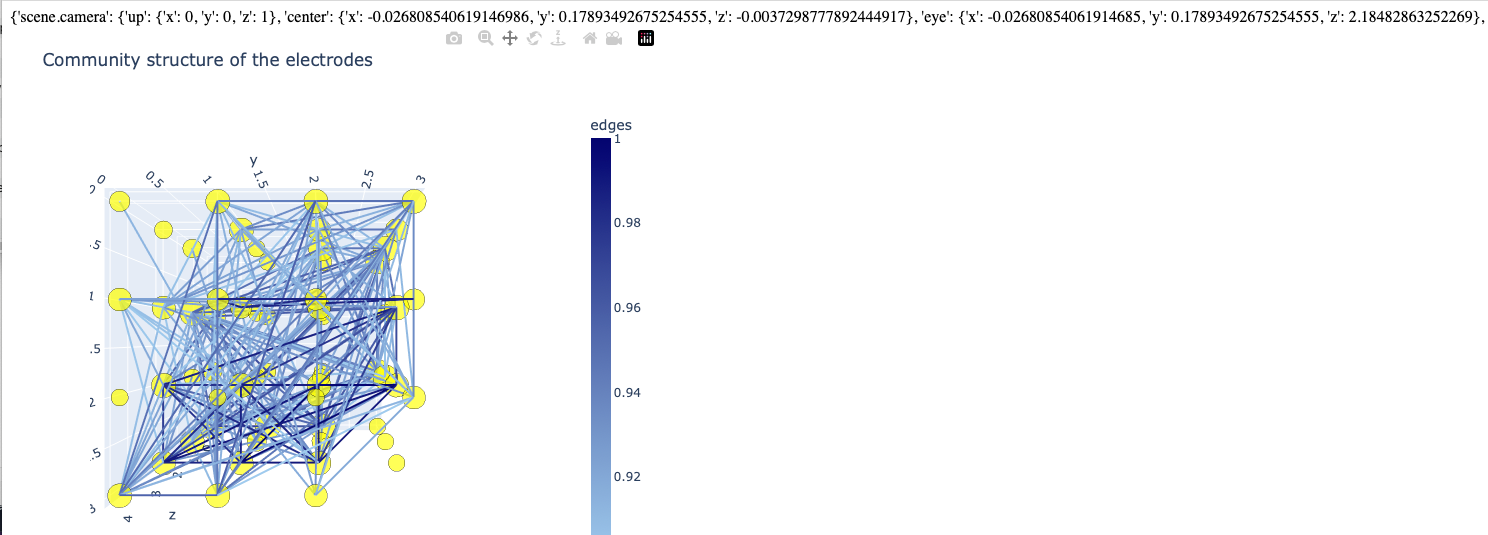

    up, center, eye의  x,y,z좌표를 가져와 아래에 순서대로 입력합니다. 또는 [https://plotly.com/python/3d-camera-controls/](https://plotly.com/python/3d-camera-controls/) 의 설명을 참고하여 값을 정합니다.

- up은 orbital rotation 기능을 사용하면 바뀌는 값입니다. 2d network에서는 사용할 일이 없습니다.

            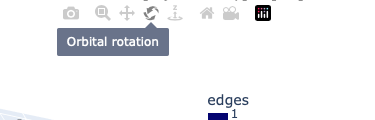

- center는 pan 기능을 사용해 plot 자체를 상하좌우로 움직이면 바뀌는 값입니다. Colorbar와 plot이 겹치지 않도록 할 때 사용합니다.

                        

- eye는 turntable rotation 기능을 사용해 plot을 돌리면 바뀌는 값입니다. html 파일을 열면 기본적으로 이 기능이 켜져 있습니다. 

                

nter':  'eye': {

%15
camera_up = [0,0,1];

%16
camera_center = [ -0.026808540619146986, 0.17893492675254555, -0.0037298777892444917];

%17
camera_eye = [-0.02680854061914685,  0.17893492675254555, 2.18482863252269]; %2d 네트워크를 위에서 볼 때는 eye 값은 이 값을 사용합니다.

- 위에서 parameter 값을 모두 설정했으므로, 아래 함수는 고칠 필요가 없습니다.

- 아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

                            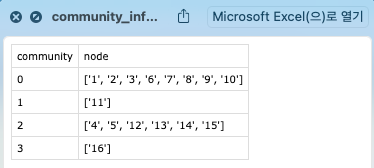

- plot은 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

                            

na.louvain(node_size_basic, node_size_multiplier, startcolor_edge, endcolor_edge , startcolor_node, endcolor_node,degree_lim, edge_lim, edge_colorbar_lim, community_colorbar_max, display_community_color, display_degree, display_sync_score, display_axes, camera_up, camera_center, camera_eye)

# **2. 3d network 그리기**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

- **network plot 그리기(3d)**

## **2.1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/mac/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
toc % 코드 실행 소요시간 측정

## **2.2. networkAnalyzer 인스턴스 생성**

input argument:

- 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- 위에서 얻은 python 설치 경로

                                                            폴더 경로                                                                                        python 설치 경로

na = networkAnalyzer("/Users/mac/GitHub/neurosignal-matlab", "/usr/local/opt/python@3.9/bin/python3.9"); %  networkAnalyzer 클래스 인스턴스 생성

## **2.3. 데이터 파일을 networkAnalyzer에 전달 **

na.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

## **2.4. 사용하지 않는 채널 제거**

이 예제에서는 1번, 8번, 64번 채널을 제거하겠습니다.

                %채널 번호
na.deleteChannel(1);
na.deleteChannel(8);
na.deleteChannel(64);

## 2.5. 채널 위치 입력

method `setChannelPosition3d`

input argument:

- channel number

- 해당 channel의 x좌표

- 해당 channel의 y좌표

- 해당 channel의 z좌표

x, y 좌표는 좌표평면의 1사분면을 생각하면 됩니다. (0,0)의 한 칸 위가 (0,1)이고 한 칸 오른쪽이 (1,0)입니다. 아래 코드로 설정한 위치를 그림으로 그리면 아래 그림처럼 됩니다.

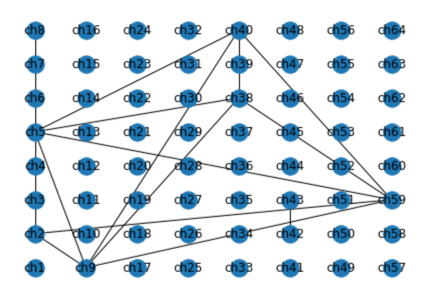

%                 channlNum x  y  z
%na.setChannelPosition3d(1 , 0, 0, 0)
na.setChannelPosition3d(2 , 0, 1, 0)
na.setChannelPosition3d(3 , 0, 2, 0)
na.setChannelPosition3d(4 , 0, 3, 0)
na.setChannelPosition3d(5 , 1, 0, 0)
na.setChannelPosition3d(6 , 1, 1, 0)
na.setChannelPosition3d(7 , 1, 2, 0)
%na.setChannelPosition3d(8 , 1, 3, 0)
na.setChannelPosition3d(9 , 2, 0, 0)
na.setChannelPosition3d(10, 2, 1, 0)
na.setChannelPosition3d(11, 2, 2, 0)
na.setChannelPosition3d(12, 2, 3, 0)
na.setChannelPosition3d(13, 3, 0, 0)
na.setChannelPosition3d(14, 3, 1, 0)
na.setChannelPosition3d(15, 3, 2, 0)
na.setChannelPosition3d(16, 3, 3, 0)

na.setChannelPosition3d(17,  0, 0, 1.5)
na.setChannelPosition3d(18,  0, 1, 1.5)
na.setChannelPosition3d(19,  0, 2, 1.5)
na.setChannelPosition3d(20,  0, 3, 1.5)
na.setChannelPosition3d(21,  1, 0, 1.5)
na.setChannelPosition3d(22,  1, 1, 1.5)
na.setChannelPosition3d(23,  1, 2, 1.5)
na.setChannelPosition3d(24,  1, 3, 1.5)
na.setChannelPosition3d(25,  2, 0, 1.5)
na.setChannelPosition3d(26,  2, 1, 1.5)
na.setChannelPosition3d(27,  2, 2, 1.5)
na.setChannelPosition3d(28,  2, 3, 1.5)
na.setChannelPosition3d(29,  3, 0, 1.5)
na.setChannelPosition3d(30,  3, 1, 1.5)
na.setChannelPosition3d(31,  3, 2, 1.5)
na.setChannelPosition3d(32,  3, 3, 1.5)

na.setChannelPosition3d(33,  0, 0, 3)
na.setChannelPosition3d(34,  0, 1, 3)
na.setChannelPosition3d(35,  0, 2, 3)
na.setChannelPosition3d(36,  0, 3, 3)
na.setChannelPosition3d(37,  1, 0, 3)
na.setChannelPosition3d(38,  1, 1, 3)
na.setChannelPosition3d(39,  1, 2, 3)
na.setChannelPosition3d(40,  1, 3, 3)
na.setChannelPosition3d(41,  2, 0, 3)
na.setChannelPosition3d(42,  2, 1, 3)
na.setChannelPosition3d(43,  2, 2, 3)
na.setChannelPosition3d(44,  2, 3, 3)
na.setChannelPosition3d(45,  3, 0, 3)
na.setChannelPosition3d(46,  3, 1, 3)
na.setChannelPosition3d(47,  3, 2, 3)
na.setChannelPosition3d(48,  3, 3, 3)
na.setChannelPosition3d(49, 0, 0, 4.5)
na.setChannelPosition3d(50, 0, 1, 4.5)
na.setChannelPosition3d(51, 0, 2, 4.5)
na.setChannelPosition3d(52, 0, 3, 4.5)
na.setChannelPosition3d(53, 1, 0, 4.5)
na.setChannelPosition3d(54, 1, 1, 4.5)
na.setChannelPosition3d(55, 1, 2, 4.5)
na.setChannelPosition3d(56, 1, 3, 4.5)
na.setChannelPosition3d(57, 2, 0, 4.5)
na.setChannelPosition3d(58, 2, 1, 4.5)
na.setChannelPosition3d(59, 2, 2, 4.5)
na.setChannelPosition3d(60, 2, 3, 4.5)
na.setChannelPosition3d(61, 3, 0, 4.5)
na.setChannelPosition3d(62, 3, 1, 4.5)
na.setChannelPosition3d(63, 3, 2, 4.5)
%na.setChannelPosition3d(64, 3, 3, 4.5)

## 2.6. 모든 채널에 bandpass 적용하고 spike detection 수행

summary_examples_firing_rate.mlx 파일의 [0.4. bandpass filter 적용] [0.5. (method) `detectSpikes] 섹션 참조`

na.bandPass([300,3000])
na.detectSpikes(4.5,2,2);

## **2.7. sync score 계산 및 확인**

figure 3 a, b, c, d, e의 (i)

pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도 (= 1 - 거리)를 측정합니다.

spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 sync score 계산값이 NaN이 됩니다.

NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

아래 사항은 아직 구현하지 않았습니다(reference 12페이지에 있는 내용) 

Since two spike trains with uniformly random activity may exhibit relatively high synchrony merely due to randomness, the SPIKE-distance from recorded data was normalized to random samples generated computationally. That is, for a pair of electrodes with $n_1$ and $n_2$ spikes,

- random spike trains were generated by **sampling $n_1$ and $n_2$ points uniformly at random in a 10-minute timeline.**

- This process was **repeated 1,000 times**, and the **average normalized score** is reported.

- thres 값을 0.9로 설정하면, sync score 0.9 이상일 경우에만 연결된 것으로 간주합니다.

thres = 0.9
na.spikeDist(thres)

### network mapping 을 위해 계산하는 parameter 확인

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na.syncScores

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na.nConnects
max(na.syncScores{:,:}) %각 channel별 sync score 최댓값

max(max(na.syncScores{:,:})) %전체 sync score 중 최댓값

na.nConnects
max(na.nConnects{:,:}) %각 channel별 degree 최댓값

max(max(na.nConnects{:,:})) %전체 degree 중 최댓값

## 2.8. network plot 그리기(3d)

figure 3 a, b, c, d, e의 (ii)

matlab에서 python을 통해 networkx로 네트워크를 만들고 louvain-python으로 community detection을 하는 것까지는 별 문제가 없으나,

네트워크 모양을 plot으로 그리는 것은 matplotlib 라이브러리를 써야 하는데, 이상하게도 matlab에서 연동이 잘 안됩니다.

차선책으로, score matrix를 파일로 저장한 다음 아예 파이썬 스크립트를 만들고 matlab에서는 해당 파이썬 스크립트를 실행하는 명령만 내리도록 조치하였습니다.

plot은 이 파일이 있는 경로에 `networkfig.html`로 저장됩니다.

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

#### 파라미터 설정

- node_size_basic

- node_size_multiplier

- startcolor_edge

- endcolor_edge

- startcolor_node

- endcolor_node

- degree_lim

- edge_lim

- edge_colorbar_lim

- community_colorbar_max

- display_community_color

- display_degree

- display_sync_score

- camera_up

- camera_center

- camera_eye

#### Node size parameters

- 노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. node size = (node_size_basic + node_size_multiplier * ( 1 + relative_degree) )

- relative_degree = max degree = 1, min degree = 0으로 normalize

%1
node_size_basic = 10;

%2
node_size_multiplier = 20;

####  Colorscale paramters

- Edge와 node의 colorscale 의 시작과 끝 색깔 코드를 hex code로 입력합니다. 저는 하늘색에서 시작해 남색에서 끝나는 것으로 했습니다.

- Hex code는 https://www.color-hex.com/ 에서 검색해서 찾으시면 됩니다.

startcolor_edge = '#9fcbee';
endcolor_edge =  '#01016f';
startcolor_node = '#9fcbee';
endcolor_node =  '#01016f';

#### Display range paramters

degree_lim = [0, 20]; %Degree가 이 범위 내에 있는 node만 plot에 표시됩니다. 앞에서 channel을 지우는 것과 달리, 계산과정 자체에는 포함됩니다. na.nConnects로 degree 범위를 확인한 다음 적절한 값을 설정하세요.
edge_lim = [0.9, 1]; % Sync score가 이 범위 내에 있는 edge만 plot에 표시됩니다. na.syncScores로 sync score 범위를 확인한 다음 적절한 값을 설정하세요.

#### Colarbar range paramters

edge_colorbar_lim = [0.9, 1]; % 여러 plot의 sync score colorbar 범위를 통일시키기 위한 기능입니다. edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.
community_colorbar_max = 30; % 여러 plot의 node colorbar 범위를 통일시키기 위한 기능입니다. degree가 아니라 comunity number를 의미합니다.
%예를 들어, 이 값을 20으로 설정하면 colorbar에서 community 번호의 범위가 1-20이 되고, 20번 커뮤니티에 가장 진한 색이 배정됩니다.
% Community는 louvain algorithm을 돌려야 알 수있으므로, 우선 큰 값으로 설정하고 코드를 끝까지 실행하신 다음,
% 생성되는 community_info.csv 파일을 보고 값을 조정하여 이 섹션만 다시 실행하시면 됩니다.

#### Display on/off options

display_community_color= true;
display_degree = true;
display_sync_score = true;
display_axes = true;

#### Camera options

- [https://wearablelab-camera-5ti4.onrender.com](https://wearablelab-camera-5ti4.onrender.com) 에서 적절한 각도를 설정한 뒤 (접속에 1분 정도 걸립니다), plot 위에 나타나는 좌표값에서

    up, center, eye의  x,y,z좌표를 가져와 아래에 순서대로 입력합니다. 또는 [https://plotly.com/python/3d-camera-controls/](https://plotly.com/python/3d-camera-controls/) 의 설명을 참고하여 값을 정합니다.

- up은 orbital rotation 기능을 사용하면 바뀌는 값입니다.

            

- center는 pan 기능을 사용해 plot 자체를 상하좌우로 움직이면 바뀌는 값입니다. Colorbar와 plot이 겹치지 않도록 할 때 사용합니다.

                        

- eye는 turntable rotation 기능을 사용해 plot을 돌리면 바뀌는 값입니다. html 파일을 열면 기본적으로 이 기능이 켜져 있습니다. 

                

camera_up = [0,0,1];
camera_center = [-0.10098346615340659,0.08859588059353385,  0.012387585559872738];
camera_eye = [1.7980575942618118, 0.12853842060263704, -1.374004869994737];

- 위에서 parameter 값을 모두 설정했으므로, 아래 함수는 고칠 필요가 없습니다.

- 아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

- plot은 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

na.louvain(node_size_basic, node_size_multiplier, startcolor_edge, endcolor_edge, startcolor_node, endcolor_node,  degree_lim, edge_lim, edge_colorbar_lim, community_colorbar_max, display_community_color, display_degree, display_sync_score, display_axes, camera_up, camera_center, camera_eye)